close all
clear all
clc

data = readmatrix("excelprogetto.xlsx","Sheet","Monthly","Range","B2:K770");

% y = IP, Infl, FedFunds, Spread, SP500
y = [100*diff(log(data(:,3))) , 100*diff(log(data(:,2))) , data(2:end,1) , data(2:end,6) , 100*diff(log(data(:,8)))];

high = data(2:end,10);

vNames = {'IP growth','Inflation','FedFunds','BAA-AAA','SP500 ret'};
shkIdx = 3; % shock MP su FedFunds (per Cholesky)

% Split dei campioni per regime
y_h = y(high==1,:);
y_l = y(high==0,:);

%% optLag (AIC)
max_p = 12;
AIC   = nan(max_p,1);
n = size(y,2);

for p = 1:max_p
    [~,res] = VARTopicsOLS(y,p);
    Teff  = size(res,1);
    Sigma = (res'*res)/Teff;
    k     = n^2*p + n;
    AIC(p)= log(det(Sigma)) + 2*k/Teff;
end

[~,popt] = min(AIC);
fprintf("Lag scelto = %d\n", popt);

Lag scelto = 10


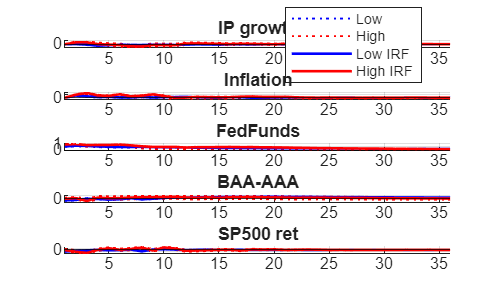


%% IRF e Bootstrap (Cholesky)
H = 36;
c = 1;
MaxBoot = 1000;
cl = [16 84];
ind = [];
opt = 0;

[cirfL,CholBootL] = CholeskyBoot(y_l,popt,H,c,MaxBoot,cl,ind,opt);
[cirfH,CholBootH] = CholeskyBoot(y_h,popt,H,c,MaxBoot,cl,ind,opt);

% Risposta a shock MP (Cholesky)
irfL = squeeze(cirfL(:,shkIdx,:));
irfH = squeeze(cirfH(:,shkIdx,:));

% Percentili bande (Cholesky)
tmpL = prctile(CholBootL(:,shkIdx,:,:),cl,4);
tmpH = prctile(CholBootH(:,shkIdx,:,:),cl,4);

bandL = permute(squeeze(tmpL),[1 3 2]);
bandH = permute(squeeze(tmpH),[1 3 2]);

%% plot cholesky
t = 1:H;
figure('Name','IRF Cholesky: Low vs High','Color','w');
for i=1:n
    subplot(n,1,i); hold on;
    plot(t, squeeze(bandL(i,1,:)), 'b:', 'LineWidth', 0.9);
    plot(t, squeeze(bandL(i,2,:)), 'b:', 'LineWidth', 0.9);
    plot(t, squeeze(bandH(i,1,:)), 'r:', 'LineWidth', 0.9);
    plot(t, squeeze(bandH(i,2,:)), 'r:', 'LineWidth', 0.9);
    plot(t, irfL(i,:), 'b', 'LineWidth', 1.3);
    plot(t, irfH(i,:), 'r', 'LineWidth', 1.3);

    yline(0,'k-');
    grid on; xlim([1 H]);
    title(vNames{i},'Interpreter','none');
    if i==1
        legend('Low','','High','','Low IRF','High IRF','Location','best');
    end
end


%% SIGN–ZERO RESTRICTIONS


kZero   = 2;          % IP, Inflation are slowmoving
lagrest = 1;          % impact horizon

% Signs for FFR, Spread, SP500
rest_z = [+1; +1; -1];  

% LOW
[medL_z, bandL_z, accL] = SignZeroRestrictBoot(y_l,popt,H,c,MaxBoot,cl,kZero,lagrest,rest_z);


--- Matrice H (Identity + Rotation) ---
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    0.4817    0.5176    0.7071
         0         0    0.2225    0.7083   -0.6700
         0         0   -0.8476    0.4801    0.2260

---------------------------------------


% HIGH
[medH_z, bandH_z, accH] = SignZeroRestrictBoot(y_h,popt,H,c,MaxBoot,cl,kZero,lagrest,rest_z);


--- Matrice H (Identity + Rotation) ---
    1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    0.9747    0.1637    0.1521
         0         0    0.0709    0.4189   -0.9052
         0         0   -0.2119    0.8931    0.3967

---------------------------------------



fprintf("Zero-sign accepted draws: LOW=%d / %d, HIGH=%d / %d\n", accL, MaxBoot, accH, MaxBoot);

Zero-sign accepted draws: LOW=1000 / 1000, HIGH=1000 / 1000


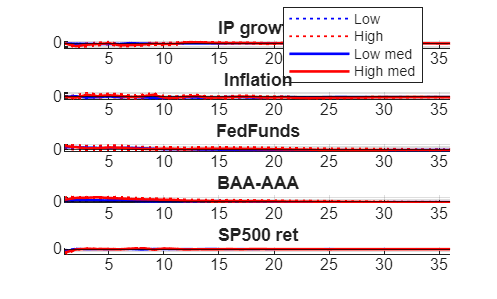


figure('Name','Sign-Zero Restrictions: Low vs High','Color','w');
for i=1:n
    subplot(n,1,i); hold on;
    plot(t, squeeze(bandL_z(i,:,1)), 'b:', 'LineWidth', 0.9);
    plot(t, squeeze(bandL_z(i,:,2)), 'b:', 'LineWidth', 0.9);
    plot(t, squeeze(bandH_z(i,:,1)), 'r:', 'LineWidth', 0.9);
    plot(t, squeeze(bandH_z(i,:,2)), 'r:', 'LineWidth', 0.9);
    plot(t, medL_z(i,:), 'b', 'LineWidth', 1.3);
    plot(t, medH_z(i,:), 'r', 'LineWidth', 1.3);

    yline(0,'k-'); grid on; xlim([1 H]);
    title(vNames{i},'Interpreter','none');
    if i==1
        legend('Low','','High','','Low med','High med','Location','best');
    end
end


%% FEVD (Cholesky)
hor = [12 24 36];
shkNames = matlab.lang.makeValidName(vNames);

[~, vdkL] = TopicsVD2(cirfL, cirfL, hor);
[~, vdkH] = TopicsVD2(cirfH, cirfH, hor);

for k = 1:numel(hor)
    ML_k = squeeze(vdkL(:,k,:));
    MH_k = squeeze(vdkH(:,k,:));
    MD_k = MH_k - ML_k;

    TL = array2table(round(ML_k,2), 'RowNames', vNames, 'VariableNames', shkNames);
    TH = array2table(round(MH_k,2), 'RowNames', vNames, 'VariableNames', shkNames);
    TD = array2table(round(MD_k,2), 'RowNames', vNames, 'VariableNames', shkNames);

    fprintf("\nFEVD @ %d mesi\n", hor(k));
    disp("LOW");  disp(TL);
    disp("HIGH"); disp(TH);
    disp("DIFF"); disp(TD);
end


FEVD @ 12 mesi


LOW
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth      0.91        0.02         0.04       0.03        0.01  
    Inflation      0.01        0.84         0.06       0.04        0.04  
    FedFunds       0.12        0.04         0.78       0.02        0.03  
    BAA-AAA        0.08        0.05         0.04       0.79        0.04  
    SP500 ret      0.03        0.02         0.05       0.02        0.88  



HIGH
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth      0.73        0.05         0.03       0.05        0.14  
    Inflation      0.07        0.66         0.16       0.09        0.02  
    FedFunds       0.06        0.12         0.68       0.12        0.02  
    BAA-AAA        0.03         0.1         0.02       0.44        0.42  
    SP500 ret      0.04        0.03         0.06       0.07         0.8  



DIFF
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth     -0.18         0.04       -0.01        0.02       0.13  
    Inflation      0.06        -0.18         0.1        0.04      -0.02  
    FedFunds      -0.07         0.08        -0.1         0.1      -0.02  
    BAA-AAA       -0.06         0.04       -0.02       -0.35       0.38  
    SP500 ret      0.02            0        0.01        0.05      -0.08  




FEVD @ 24 mesi


LOW
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth       0.9        0.02         0.04       0.03        0.01  
    Inflation      0.02        0.82         0.06       0.04        0.06  
    FedFunds       0.15        0.12         0.61       0.03        0.09  
    BAA-AAA        0.07        0.21         0.11       0.57        0.04  
    SP500 ret      0.03        0.03         0.05       0.02        0.87  



HIGH
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth      0.72        0.05         0.03       0.05        0.14  
    Inflation      0.07        0.63         0.16       0.11        0.03  
    FedFunds       0.05        0.19         0.61       0.13        0.02  
    BAA-AAA        0.03        0.15         0.03       0.38        0.41  
    SP500 ret      0.05        0.03         0.06       0.07        0.79  



DIFF
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth     -0.18         0.03       -0.01        0.03       0.13  
    Inflation      0.05        -0.19         0.1        0.06      -0.02  
    FedFunds       -0.1         0.07           0         0.1      -0.07  
    BAA-AAA       -0.04        -0.06       -0.09       -0.19       0.37  
    SP500 ret      0.02         0.01        0.01        0.05      -0.09  




FEVD @ 36 mesi


LOW
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth      0.89        0.03         0.04       0.03        0.01  
    Inflation      0.02        0.82         0.05       0.04        0.06  
    FedFunds       0.15        0.17         0.54       0.03        0.11  
    BAA-AAA        0.06        0.31         0.12       0.44        0.06  
    SP500 ret      0.03        0.03         0.05       0.02        0.87  



HIGH
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth      0.72        0.06         0.03       0.05        0.14  
    Inflation      0.07        0.62         0.16       0.11        0.04  
    FedFunds       0.04         0.2         0.58       0.15        0.03  
    BAA-AAA        0.03        0.15         0.03       0.38        0.41  
    SP500 ret      0.05        0.03         0.06       0.07        0.78  



DIFF
                 IPGrowth    Inflation    FedFunds    BAA_AAA    SP500Ret
                 ________    _________    ________    _______    ________

    IP growth     -0.18         0.03       -0.01        0.03       0.13  
    Inflation      0.05         -0.2         0.1        0.07      -0.02  
    FedFunds      -0.11         0.03        0.04        0.12      -0.08  
    BAA-AAA       -0.03        -0.16        -0.1       -0.05       0.35  
    SP500 ret      0.02         0.01        0.01        0.05      -0.09  

